# Gerenerates plot of axisymetric inlet spike

clear; close; clc;

## Initialize Variables

inletSpikeFileName = "Axisymmetric_Isentroipc_Spike_M4.xlsx"

inletSpikeFileName = "Axisymmetric_Isentroipc_Spike_M4.xlsx"

## import table

[x_2_r, y_2_r, x_f_2_r, y_f_2_r, M_s, lambda_s, M_f, lambda_s1] = importAxisymmetricSpike(inletSpikeFileName)

x_2_r =     1.1288
    1.5141
    1.7899
    2.0188
    2.2098
    2.3716
    2.5045
    2.6254
    2.7173
    2.8000
    2.8697
    2.9289
    2.9798
    3.0229
    3.0596


y_2_r =     0.1889
    0.2609
    0.3185
    0.3736
    0.4253
    0.4737
    0.5173
    0.5611
    0.5972
    0.6337
    0.6671
    0.6979
    0.7263
    0.7537
    0.7784


x_f_2_r = 3.1910

y_f_2_r = 1

M_s =     3.6200
    3.5000
    3.4100
    3.3200
    3.2300
    3.1400
    3.0400
    2.9500
    2.8600
    2.7700
    2.6700
    2.5800
    2.4800
    2.3800
    2.2900


lambda_s =     9.5000
   11.4000
   12.9000
   14.3000
   15.9000
   17.4000
   19.1000
   20.9000
   22.6000
   24.6000
   26.5000
   28.6000
   30.7000
   33.0000
   35.3000


M_f =     3.7000
    3.6000
    3.5000
    3.4000
    3.3000
    3.2000
    3.1000
    3.0000
    2.9000
    2.8000
    2.7000
    2.6000
    2.5000
    2.4000
    2.3000


lambda_s1 =     4.2000
    5.7100
    7.2700
    8.9000
   10.6000
   12.3000
   14.2000
   16.0000
   18.0000
   20.1000
   22.2000
   24.4000
   26.7000
   29.1000
   31.5000


## plot results

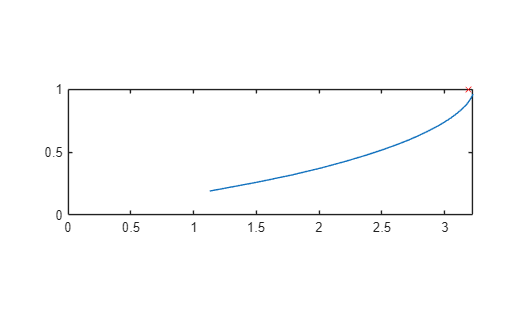

plot(x_2_r,y_2_r);
hold on;
plot(x_f_2_r, y_f_2_r, "rx")
axis("equal");
xlim([0,max(x_2_r)]); ylim([0,y_f_2_r]);

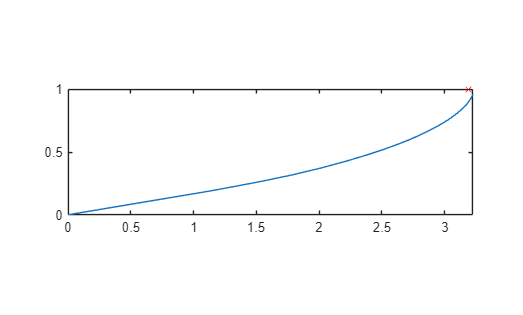


% do the same thing but include the conical tip
figure;
plot([0;x_2_r], [0;y_2_r]);
hold on;
plot(x_f_2_r, y_f_2_r, "rx")
axis("equal");
xlim([0,max(x_2_r)]); ylim([0,y_f_2_r]);


% compute the inlet length
Length_inlet = sqrt((x_f_2_r - x_2_r(end)).^2 + (y_f_2_r - y_2_r(end)).^2)

Length_inlet = 0.0518

Length_inlet_2_r = Length_inlet

Length_inlet_2_r = 0.0518


hight_inlet_anulus_2_r = y_f_2_r - y_2_r(end)

hight_inlet_anulus_2_r = 0.0384

width_inlet_anulus_2_r = x_2_r(end) - x_f_2_r

width_inlet_anulus_2_r = 0.0348

radius_spike = y_2_r(end)

radius_spike = 0.9616